function probitplot(M)
    dec=unique(M(:,3));
    x=M(:,2);
    y=M(:,5);
    N=zeros(max(x),1);
    n_=zeros(max(x),1);
    for i=min(x):max(x)
        N(i+1)=sum(x==i);
        n_(i+1)=sum(y(x==i));
    end
    n=max(0,2*n_-N);
    
    b=glmfit(dec,[n,N],"binomial","Link","probit");
    yfit=glmval(b,dec,"probit","size",N);
    plot(dec,n./N,"o",dec,yfit./N,"-","LineWidth",2);
    sigma=1/b(2)
    mu=-b(1)*sigma
end

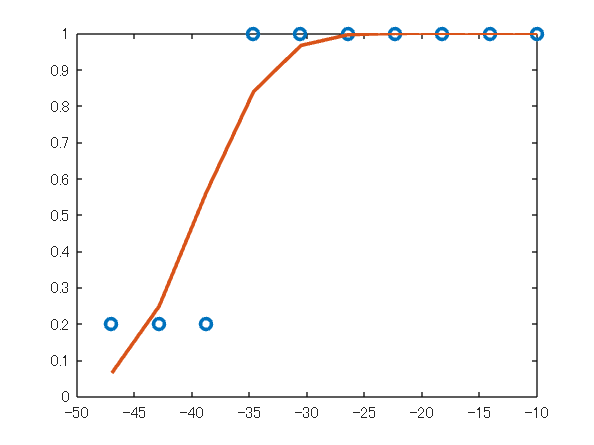

sigma = 4.9134

mu = -39.5505

M=readmatrix("ResC01.dat");
probitplot(M);

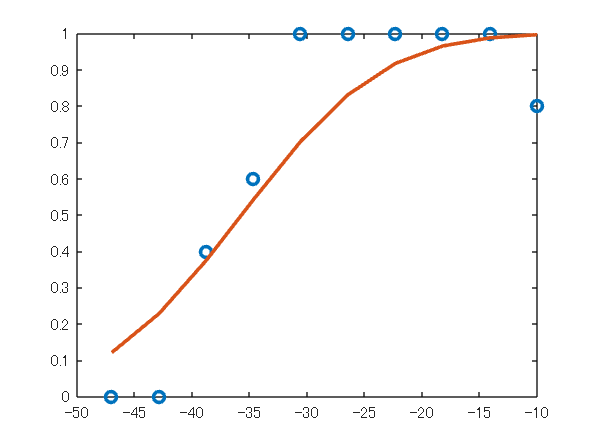

sigma = 9.6502

mu = -35.7068

M=readmatrix("ResC11.dat");
probitplot(M);

function logitplot(M)
    dec=unique(M(:,3));
    x=M(:,2);
    y=M(:,5);
    N=zeros(max(x),1);
    n_=zeros(max(x),1);
    for i=min(x):max(x)
        N(i+1)=sum(x==i);
        n_(i+1)=sum(y(x==i));
    end
    n=max(0,2*n_-N);

    beta=fminsearch(@stat,[10,1]);
    border=-1*beta(1)/beta(2)

    function l=stat(b)
        l=0;
        for i = 1:10
            l=l-log(nchoosek(10,n(i)))-n(i)*log((exp(b(1)+b(2)*dec(i)))/(1+exp(b(1)+b(2)*dec(i)))) - (10-n(i))*log(1/(1+exp(b(1)+b(2)*dec(i))));
        end
    end
end

M=readmatrix("ResC01.dat");
logitplot(M);

border = -39.2603

M=readmatrix("ResC11.dat");
logitplot(M);

border = -36.1130

function senseplot(t,freqs)
    n=length(freqs);
    x=zeros(n,1);
    y=zeros(n,1);
    for i = 1:n
        tmp=readmatrix("ResQ"+t+freqs(i)+".dat");
        x(i)=freqs(i);
        y(i)=1/tmp(100,3);
    end
    p=polyfit(x,y,2)
    % y=ax^2+bx+c
    % y=a(x+b/2a)^2+c-b^2/4a
    mu=-p(2)/(2*p(1))
    vert=1/(p(3)-p(2).^2/(4*p(1)))
    x2=linspace(min(freqs)-1,max(freqs)+1,100);
    y2=polyval(p,x2);
    
    plot(x,y,"o",x2,y2,"LineWidth",2);
end

p =    -0.0003    0.0017   -0.0284


mu = 2.8620

vert = -38.5729

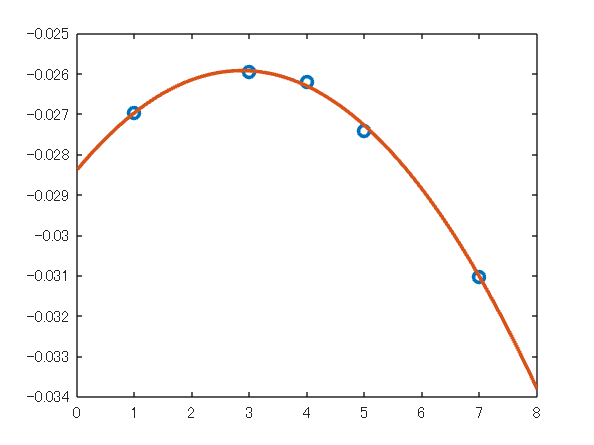

senseplot("0",[1,3,4,5,7]);

p =    -0.0003    0.0015   -0.0277


mu = 2.4939

vert = -38.7701

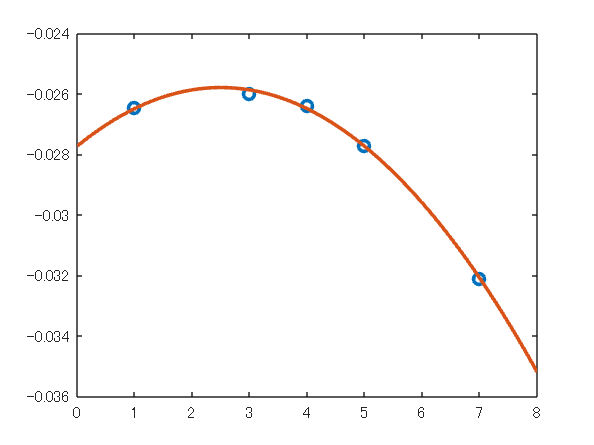

senseplot("1",[1,3,4,5,7]);